load('AnalogData.mat');
rawData = out.AnalogData

rawData =           45        2119
          45        2162
          45        2138
          45        2135
          45        2137
          45        2127
          45        2134
          45        2136
          45        2136
          45        2134


% Data from Magnetic Sensor
Nround = 13; % 45 : -3 : 9
Nsample = 501;

% Manipulate matrix
distanceData = rawData(:, 1)

distanceData =     45
    45
    45
    45
    45
    45
    45
    45
    45
    45


analogs = rawData(:, 2)

analogs =         2119
        2162
        2138
        2135
        2137
        2127
        2134
        2136
        2136
        2134


anaData = reshape(analogs, [Nsample, Nround])'

anaData =         2119        2162        2138        2135        2137        2127        2134        2136        2136        2134        2119        2128        2130        2152        2135        2123        2136        2134        2127        2115        2133        2128        2138        2123        2142        2158        2149        2130        2125        2138        2130        2134        2134        2122        2125        2135        2124        2165        2123        2129        2119        2119        2131        2136        2117        2121        2131        2145        2139        2166
        2149        2185        2136        2151        2142        2138        2142        2137        2144        2150        2137        2126        2137        2149        2174        2141        2152        2154        2143        2138        2143        2142        2149        2144        2150        2161        2144        2135        2136        2149        2151        2141     


% to be used
anaData = cast(anaData, "double");
voltData = anaData .* 3.3 ./ 4096.0

voltData =     1.7072    1.7418    1.7225    1.7201    1.7217    1.7136    1.7193    1.7209    1.7209    1.7193    1.7072    1.7145    1.7161    1.7338    1.7201    1.7104    1.7209    1.7193    1.7136    1.7040    1.7185    1.7145    1.7225    1.7104    1.7257    1.7386    1.7314    1.7161    1.7120    1.7225    1.7161    1.7193    1.7193    1.7096    1.7120    1.7201    1.7112    1.7443    1.7104    1.7153    1.7072    1.7072    1.7169    1.7209    1.7056    1.7088    1.7169    1.7281    1.7233    1.7451
    1.7314    1.7604    1.7209    1.7330    1.7257    1.7225    1.7257    1.7217    1.7273    1.7322    1.7217    1.7128    1.7217    1.7314    1.7515    1.7249    1.7338    1.7354    1.7265    1.7225    1.7265    1.7257    1.7314    1.7273    1.7322    1.7410    1.7273    1.7201    1.7209    1.7314    1.7330    1.7249    1.7354    1.7233    1.7290    1.7233    1.7169    1.7491    1.7290    1.7249    1.7322    1.7257    1.7281    1.7257    1.7249    1.7257    1.7233    1.7201    1.72

voltData = voltData(end:-1:1, :) % reverse order to 9 ... 45

voltData =     3.2702    3.2710    3.2694    3.2694    3.2710    3.2646    3.2702    3.2702    3.2718    3.2694    3.2710    3.2670    3.2718    3.2734    3.2702    3.2654    3.2702    3.2694    3.2702    3.2702    3.2702    3.2702    3.2686    3.2702    3.2694    3.2702    3.2686    3.2702    3.2702    3.2702    3.2694    3.2702    3.2702    3.2702    3.2710    3.2686    3.2694    3.2702    3.2702    3.2702    3.2702    3.2694    3.2694    3.2710    3.2702    3.2758    3.2710    3.2694    3.2702    3.2686
    3.2718    3.2710    3.2734    3.2718    3.2726    3.2694    3.2726    3.2726    3.2742    3.2718    3.2686    3.2718    3.2718    3.2726    3.2726    3.2702    3.2710    3.2726    3.2710    3.2726    3.2718    3.2702    3.2710    3.2734    3.2718    3.2718    3.2726    3.2726    3.2734    3.2670    3.2734    3.2718    3.2710    3.2726    3.2702    3.2718    3.2718    3.2726    3.2726    3.2718    3.2742    3.2718    3.2718    3.2774    3.2734    3.2726    3.2718    3.2726    3.26


meanVoltData = mean(voltData, 2) %%((mean(voltData, 2)/3.3) *100)

meanVoltData =     3.2700
    3.2723
    3.0615
    2.5030
    2.1865
    1.9973
    1.8930
    1.8297
    1.7910
    1.7624


%meanVoltData = meanVoltData(end:-1:1) % reverse order
measureX = 9 : 3 : 45

measureX =      9    12    15    18    21    24    27    30    33    36    39    42    45


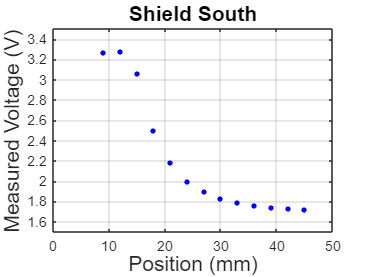

% Plotting
measureGraph = plot(measureX, meanVoltData, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% ตกแต่ง
xticks(0:10:50);
xticklabels(0:10:50);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Shield South', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Measured Voltage (V)', 'FontSize', 14); 

% Calculate Errors
stdErr = 2 .* std(voltData, 0, 2) % plot with 2SD for 95% confidence interval

stdErr =     0.0031
    0.0029
    0.0138
    0.0202
    0.0186
    0.0176
    0.0164
    0.0178
    0.0167
    0.0162


% 1SD is also OK

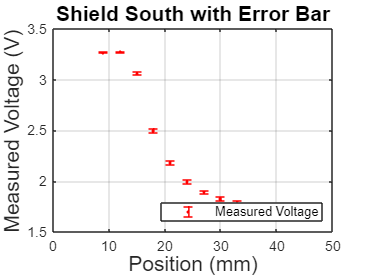

% Plotting Graph with Error

%measureGraph;
%hold on;

errorbar(measureX, meanVoltData, stdErr, 'or', 'LineWidth', 1, 'MarkerSize', 1, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); 
hold off;
% Add on
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Shield South with Error Bar', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Measured Voltage (V)', 'FontSize', 14); 